# Task 6

# A)

Checking the stability of system below.

Ag=[0 0 0 1 0 0;0 0 0 0 1 0;0 0 0 0 0 1;...
    7.3809 0 0 0 2 0;0 -2.1904 0 -2 0 0;0 0 -3.1904 0 0 0]

Ag =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
    7.3809         0         0         0    2.0000         0
         0   -2.1904         0   -2.0000         0         0
         0         0   -3.1904         0         0         0


Bg=[[0 0 0 1 0 0]' [0 0 0 0 1 0]' [0 0 0 0 0 1]']

Bg =      0     0     0
     0     0     0
     0     0     0
     1     0     0
     0     1     0
     0     0     1



e=eig(Ag)

e =   -2.1587 + 0.0000i
   2.1587 + 0.0000i
   0.0000 + 1.8626i
   0.0000 - 1.8626i
   0.0000 + 1.7862i
   0.0000 - 1.7862i


The equilibrium point in not a stable position because one pole is on the right side of the complex plane.

# B-C) 

Controllability:

system_order = length(Ag)

system_order = 6

M = ctrb(Ag, Bg(:,1));
rank_of_M = rank(M)

rank_of_M = 4

M = ctrb(Ag, Bg(:,2));
rank_of_M = rank(M)

rank_of_M = 4

M = ctrb(Ag, Bg(:,3));
rank_of_M = rank(M)

rank_of_M = 2

From the fact that the controllability matrix for u1 u2 and u3 is of lower rank than the order of the system we conclude the system is not controllable from any input u.

# D)

Determining the transfer function for y=[0 1 0 0 0 0]x

Cg=[0 1 0 0 0 0];
Dg=0;

[NUM,DEN]=ss2tf(Ag,Bg(:,2),Cg,Dg)

NUM =          0         0    1.0000    0.0000   -4.1905    0.0000  -23.5480


DEN =     1.0000    0.0000    1.9999    0.0000  -19.9653    0.0000  -51.5796


sys=tf(NUM,DEN)

sys =
 
              s^4 + 4.441e-16 s^3 - 4.191 s^2 + 1.776e-15 s - 23.55
  -----------------------------------------------------------------------------
  s^6 + 1.943e-16 s^5 + 2 s^4 + 3.325e-15 s^3 - 19.97 s^2 + 8.629e-15 s - 51.58
 
Continuous-time transfer function.



# E)

Controlabillity for y=[0 1 0 0 0 0]x

zeros=zero(sys)

zeros =   -2.7168 + 0.0000i
   2.7168 + 0.0000i
   0.0000 + 1.7862i
   0.0000 - 1.7862i


poles=pole(sys)

poles =   -2.1587 + 0.0000i
   2.1587 + 0.0000i
   0.0000 + 1.8626i
   0.0000 - 1.8626i
  -0.0000 + 1.7862i
  -0.0000 - 1.7862i


K=1;
zeros=[zeros(1:2)]

zeros =    -2.7168
    2.7168


poles=[poles(1:4)]

poles =   -2.1587 + 0.0000i
   2.1587 + 0.0000i
   0.0000 + 1.8626i
   0.0000 - 1.8626i


sys=zpk(zeros,poles,K)

sys =
 
         (s+2.717) (s-2.717)
  ---------------------------------
  (s+2.159) (s-2.159) (s^2 + 3.469)
 
Continuous-time zero/pole/gain model.



NUM=conv([1 2.717],[1 -2.717])

NUM =     1.0000         0   -7.3821


DEN=conv([1 2.159],[1 -2.159]);
DEN=conv(DEN,[1 0 3.469])

DEN =     1.0000         0   -1.1923         0  -16.1700


[A,B,C,D] = tf2ss(NUM,DEN)

A =          0    1.1923         0   16.1700
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


B =      1
     0
     0
     0


C =          0    1.0000         0   -7.3821


D = 0


system_order = length(A)

system_order = 4

M = ctrb(A,B);
rank_of_M = rank(M)

rank_of_M = 4

N = obsv(Ag, Cg);
rank_of_N = rank(N)

rank_of_N = 4

The system is now controllable given the uniformity of the rank of controllability matx with system order.

# F)

Designing a controller for system stabilisation. 

desiredpoles = [-1+1i;-1-1i;-10;-10]

desiredpoles =   -1.0000 + 1.0000i
  -1.0000 - 1.0000i
 -10.0000 + 0.0000i
 -10.0000 + 0.0000i


K = acker(A,B,desiredpoles)

K =    22.0000  143.1923  240.0000  216.1700



[num2,den2] = ss2tf(A - B * K,B,C,D);
G = tf(num2,den2)

G =
 
              s^2 - 7.382
  ------------------------------------
  s^4 + 22 s^3 + 142 s^2 + 240 s + 200
 
Continuous-time transfer function.



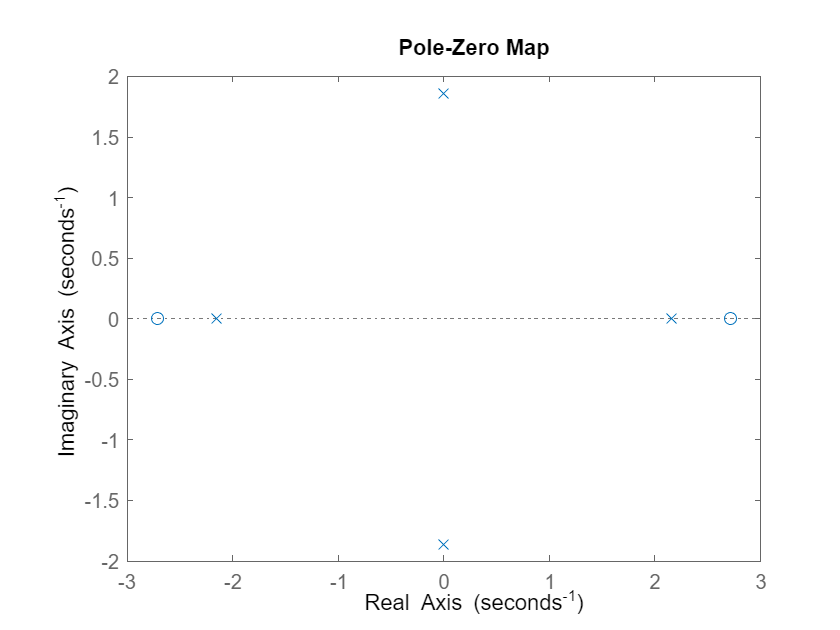

pzmap(sys)

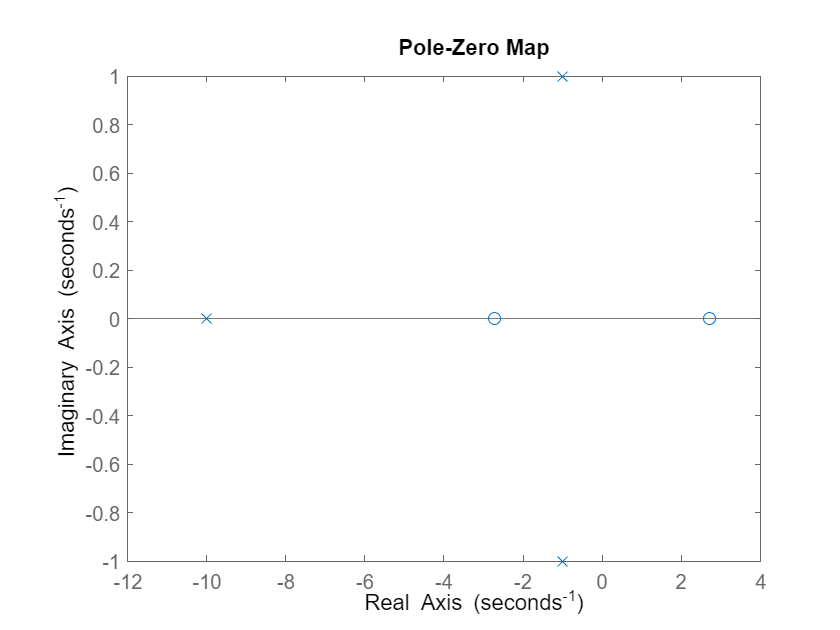

pzmap(G)

roots(den2)

ans =  -10.0000 + 0.0000i
 -10.0000 - 0.0000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i


No positve real parts of poles imply stabilized system.